# DSZOB, cvičenie 10.

## **Zadanie: JPEG kompresia**

Napíšte základný algoritmus pre JPEG kompresiu a dekompresiu - viď prednášky.

Implementujte aj downsampling kanalov Cb a Cr. (Zig-zag algoritmus už neimplementujte.)

Pomôcky: rgb2ycbcr(RGB), dct2()

Umožnite jednoduchým nastavením atribútu “kvalita” ovplyvniť mieru kompresie obrázka.

• Kvalitatívne **vyhodnoťte** vplyv atribútu “kvalita” na výslednú stratu kvality obrázka. Pri akej hodnote atribútu došlo k rozpoznateľnej strate kvality ?

• Kvantitatívne **vyhodnoťte** kompresný pomer pre rôzne hotnoty atribútu “kvalita”.

Výsledky v dostatočnej miere dokladujte vizualizáciami. Vizualizujte komprimované obrázky pre rôzne hodnoty atribútu “kvalita”.

Ako vstupné dáta použite:

- ľubovoľnú fotografiu

- syntetický obrázok (napr. nakresleny v paint-e)  

obe v bezstratovom formate ako napr. BMP, PNG ...

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

% Riesenie / Solution

QL = [16 11 10 16 24 40 51 61
12 12 14 19 26 58 60 55
14 13 16 24 40 57 69 56
14 17 22 29 51 87 80 62
18 22 37 56 68 109 103 77
24 35 55 64 81 104 113 92
49 64 78 87 103 121 120 101
72 92 95 98 112 100 103 99]

QL =     16    11    10    16    24    40    51    61
    12    12    14    19    26    58    60    55
    14    13    16    24    40    57    69    56
    14    17    22    29    51    87    80    62
    18    22    37    56    68   109   103    77
    24    35    55    64    81   104   113    92
    49    64    78    87   103   121   120   101
    72    92    95    98   112   100   103    99



QC = [17 18 24 47 99 99 99 99
18 21 26 66 99 99 99 99
24 26 56 99 99 99 99 99
47 66 99 99 99 99 99 99
99 99 99 99 99 99 99 99
99 99 99 99 99 99 99 99
99 99 99 99 99 99 99 99
99 99 99 99 99 99 99 99]

QC =     17    18    24    47    99    99    99    99
    18    21    26    66    99    99    99    99
    24    26    56    99    99    99    99    99
    47    66    99    99    99    99    99    99
    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99
    99    99    99    99    99    99    99    99


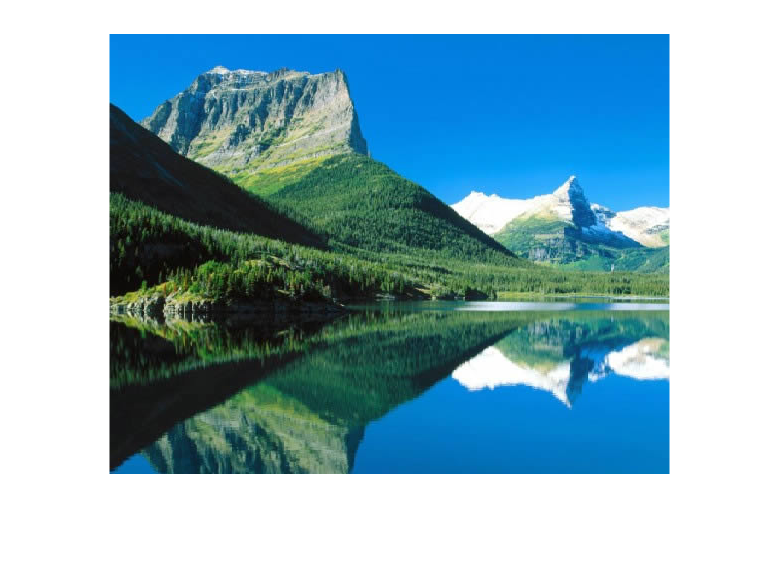

img_rgb = imread('Untitled.bmp');
figure();
imshow(img_rgb)

[img_compressed, rate] = compress(img_rgb, 8, QL, QC, 10);
rate

rate = 0.9752

Keď skomprimujem obrázok na 10% kvality dostanem kompresný pomer  alebo teda úsporu miesta až 97%.

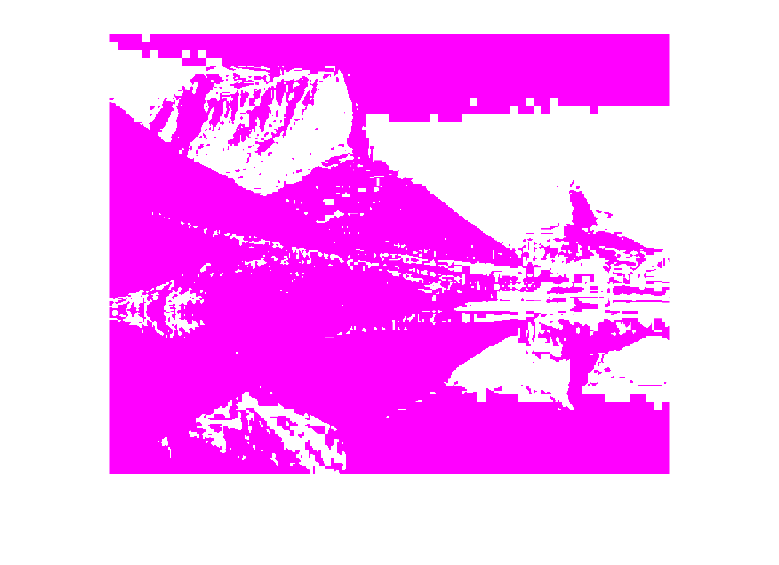

imshow(decompress(img_compressed, 8, QL, QC, 10), [])

Pravdepodobne je tu niekde však chyba, pretože dekompresiou dostaneme deformovaný obrázok.

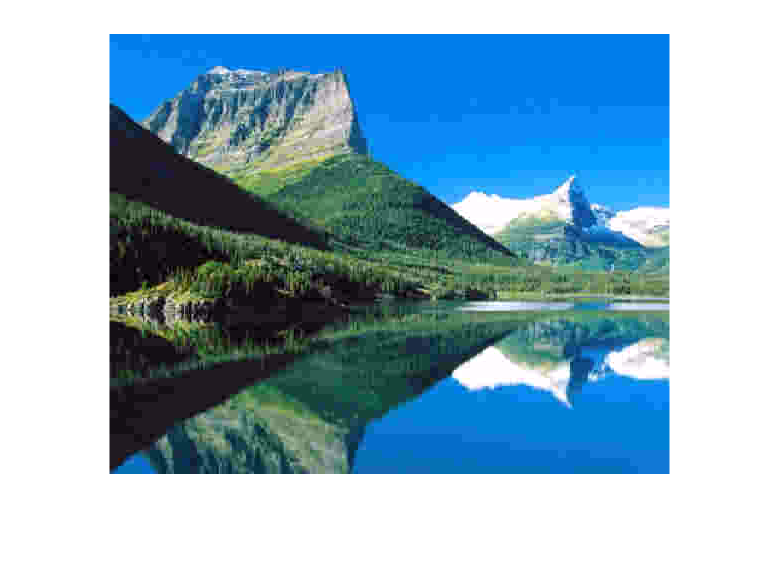

imshow(decompress(img_compressed, 8, QL, QC, 99), [])

Túto chybu som však nebol schopný lokalizovať a navyše sa prejavuje veľmi zvláštne pretože keď ten istý skomprimovaný obrázok (10% kvality) dekomprimujem s predpokladom, že bol obrázok komprimovaný na 99% kvality, čo je samozrejme absurdné, ale dostaneme veľmi pekný dekomprimovaný obrázok a to aj napriek takému podielu núl v komprimovanej verzii.

Z dôvodu pretrvávania tejto chyby som neimplementoval ani downsampling CB a CR kanálov. Toto by však bolo realiyované pomocou natívnej funkcie downsample(), ktorá ponechá napr každý druhý prvok v oboch smeroch. Túto by sme použili na každé okienko (len pre kanály CB a CR) pred DCT pri kompresii.

Pri dekompresii by bola naopak použitá pre každé okienko CB a CR kanálov po IDCT moja custom funkcia (double_dimensions), ktorá zdvojnásobí počet hodnôt a dopočíta hodnoty medzi existujúcimi.

function [result, rate] = compress(src_img, win_size, QL, QC, quality)
    img = rgb2ycbcr(src_img); % Transformacia farebneho modelu
    img_y  = img(:,:,1); %
    img_cb = img(:,:,2); % Rozdelenie kanalov
    img_cr = img(:,:,3); %
    img_height = height(img);                
    img_width = width(img);                  
    result = zeros(img_height, img_width,3); % Inicializacia vysledku

    if quality > 50                 %
        alpha = 2 - quality / 50;   %
    else                            % Vypocet alfy
        alpha = 50 / quality;       %
    end                             %


    for y = 1:win_size:img_height
        for x = 1:win_size:img_width
            window_y  = img_y (y:y+win_size-1, x:x+win_size-1); %
            window_cb = img_cb(y:y+win_size-1, x:x+win_size-1); % Vyber okienka pre kazdy kanal zvlast 
            window_cr = img_cr(y:y+win_size-1, x:x+win_size-1); %
            % Tu by pribudol downsampling
            result(y:y+win_size-1, x:x+win_size-1, 1) = round(dct2(window_y)  ./ (alpha * QL)); %
            result(y:y+win_size-1, x:x+win_size-1, 2) = round(dct2(window_cb) ./ (alpha * QC)); % Vypocet DCT a kvantizacia prislusnymi maticami
            result(y:y+win_size-1, x:x+win_size-1, 3) = round(dct2(window_cr) ./ (alpha * QC)); %
        end
    end

    rate = sum(sum(sum(result==0))) / (img_height * img_width * 3); % Vypocet kompresneho pomeru
end

function result = decompress(compressed_img, win_size, QL, QC, quality)
    img_y  = compressed_img(:,:,1); %
    img_cb = compressed_img(:,:,2); % Rozdelenie na kanaly 
    img_cr = compressed_img(:,:,3); %
    img_height = height(compressed_img);
    img_width = width(compressed_img);
    result = zeros(img_height, img_width,3); % Inicializacia vysledku

    if quality > 50                 %
        alpha = 2 - quality / 50;   %
    else                            % Vypocet alfy
        alpha = 50 / quality;       %
    end                             %

    for y = 1:win_size:img_height
        for x = 1:win_size:img_width
            window_y  = img_y (y:y+win_size-1, x:x+win_size-1); %
            window_cb = img_cb(y:y+win_size-1, x:x+win_size-1); % Vyber okienka pre kazdy kanal zvlast 
            window_cr = img_cr(y:y+win_size-1, x:x+win_size-1); %
            result(y:y+win_size-1, x:x+win_size-1, 1) = idct2(window_y  .* (alpha * QL)); %
            result(y:y+win_size-1, x:x+win_size-1, 2) = idct2(window_cb .* (alpha * QC)); % Spatne nasobenie kvantizacnymi maticami a IDCT
            result(y:y+win_size-1, x:x+win_size-1, 3) = idct2(window_cr .* (alpha * QC)); %
            % upsampling pred priradenim do result
        end
    end
    
    result = ycbcr2rgb(result); % Spatna transformacia farebneho modelu
end

function result = double_dimensions(matrix)
    result = zeros(2*height(matrix),2*width(matrix)); % Init vysledku
    tmp = interp2(matrix); % Hodnoty zdvojnasobene pomocou interpolacie

    result(1:end-1, 1:end-1) = tmp;                         %
    result(1:end-1, end) = 2*tmp(:, end) - tmp(:, end-1);   % Doplnenie podledneho riadku a stlpca
    result(end, 1:end-1) = 2*tmp(end, :) - tmp(end-1, :);   %
    result(end, end) = 2*tmp(end, end) - tmp(end-1, end-1); %
end